mat_dir_path = "/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Strujni/Mat_files";
picture_path = "/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Strujni/Slike_CV";

load (mat_dir_path + "/Samsung_30Q_18650_pack.mat");
load (mat_dir_path + "/VoltaicSystems_P110.mat");
load (mat_dir_path + "/Realisticno_ozracenje.mat");
load (mat_dir_path + "/MPP_param.mat");
load (mat_dir_path + "/CV_param.mat");

addpath(genpath("Functions"));
addpath("Simulink/");

## Boost param:

% Switching frequency:
boost.f = 1 * 10^5; % [Hz]
boost.T = 1/boost.f;

% Measurement filter cut-off:
boost.mfc = 2000; %[Hz]
boost.Tmfc = 1/(2*pi*boost.mfc);

% Granicni uvjet filter:
boost.Tgf = 1/(pi*1000);

% Maximum duty cycle that can be achieved:
boost.D_max = 1 - pv_data.Umpp/Bat.Ubat_nom; % MPP mode of operation

% Passive elements:
boost.Rt = 1*10^5;
boost.RL = 100 * 10^-3;
boost.Ru = 1;
boost.L = 40 * 10^-6;
boost.Cu = 1500 * 10^-6;
boost.Ci = 1200 * 10^-6;
boost.Cbat = (Bat.Qbat_tot)/(Bat.Ubat_charged - Bat.Ubat_cut_off);

## PV setup:

% CCM:
pv_in.G = 800;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv = calc_pv_res("Solar_v2", pv_in);

## Operating point:

sim_op.Upv0 = pv.Umpp;
sim_op.Ipv0 = pv.Impp;
sim_op.Ubat0 = Bat.Ubat_nom;
sim_op.E0 = Bat.Ebat_min + (sim_op.Ubat0 - Bat.Ubat_cut_off)*1/Bat.nagib;

% sim_op.m0 = 3.0002e+04;
sim_op.m0 = 2.0825e+04

sim_op = struct with fields:
     Upv0: 5.7000
     Ipv0: 1.4690
    Ubat0: 10.8000
       E0: 3.5640e+04
       m0: 20825


## Irradiance signal

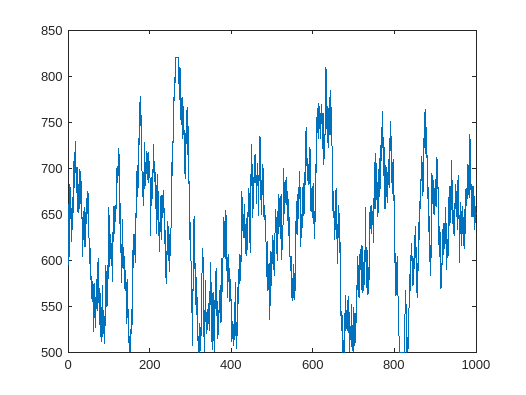

sim_time = 1000;
Tstep = sim_time/20000;

GI = irradiance_signal_real(sim_time, Tstep, 500, 820);

figure;
plot(GI.Time, GI.Data);